## Integrals in MATLAB

This MATLAB live script includes some exercises to calculate integrals numerically and symbolically. Prepared for EAS Practical Coding and Math course at Georgia Tech.

### Numerical integrals

First lets define a function $y = e^{-x} \sin(x^2)$ which is very difficult to analytically integrate

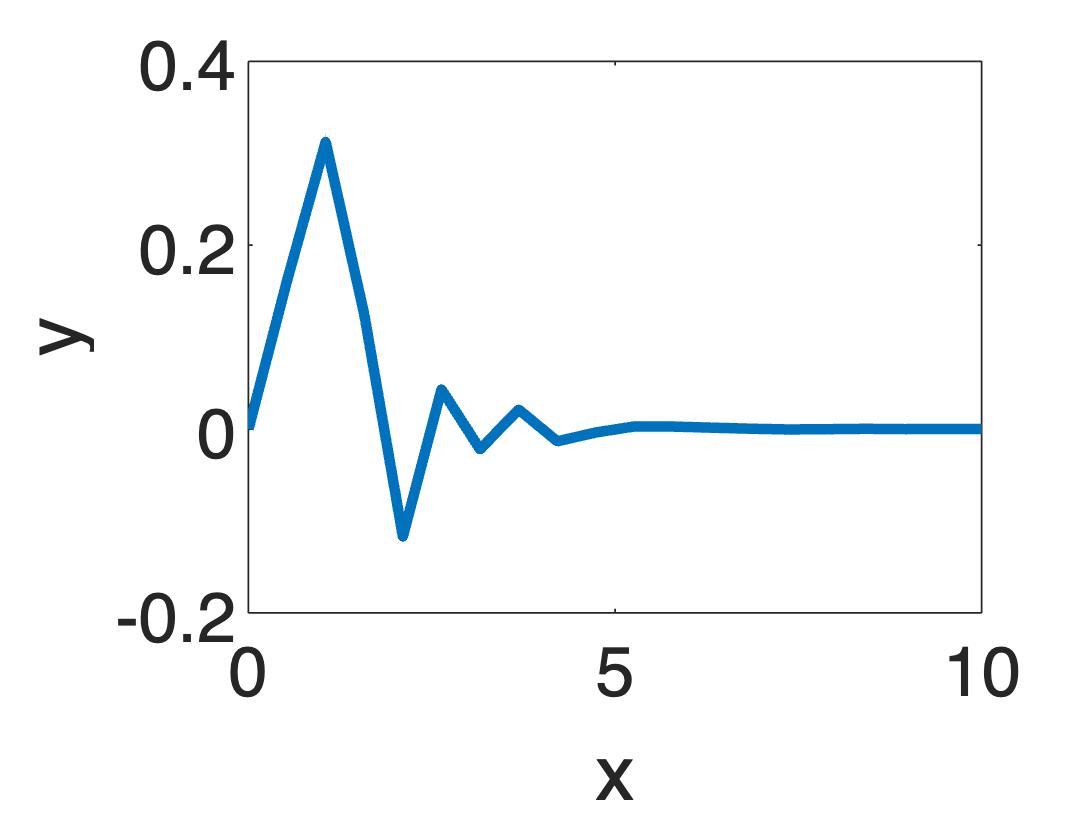

x = linspace(0,10,20);
y = exp(-x).*sin(x.^2);
plot(x,y,'linewidth',3)
xlabel('x','FontSize',20)
ylabel('y','FontSize',20)
set(gca,'fontsize',20)

Probably the most obvious way to calculate the integral is by summing over y*dx, which uses the conceptual definition of an integral (summing over rectangles under the curve) to calculate the integral numerically

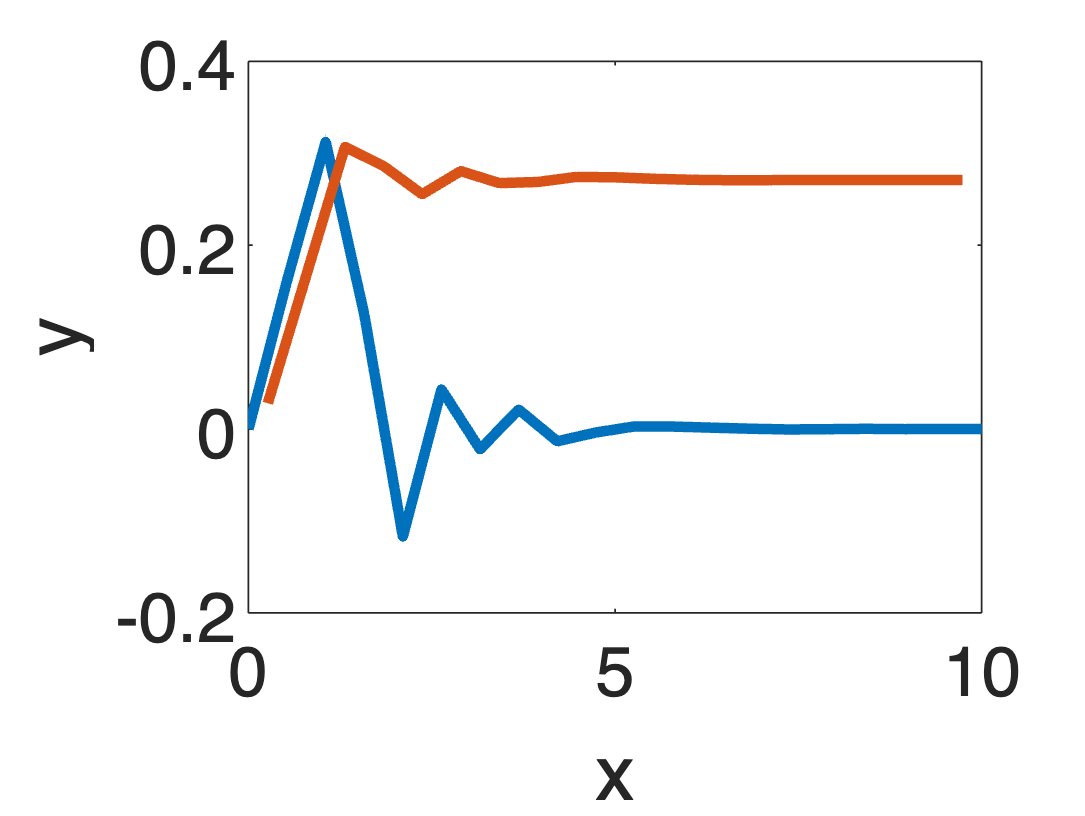

xmid = (x(1:end-1)+x(2:end))/2; %ymid is the midpoint value of y on each interval (rectangle)
dx = diff(x,1);
ymid = exp(-xmid).*sin(xmid.^2);
inty = cumsum(ymid.*dx); %cumsum calculates the cumulative sum over a vector 

plot(x,y,'linewidth',3);hold on
xlabel('x','FontSize',20)
ylabel('y','FontSize',20)
set(gca,'fontsize',20)

plot(xmid,inty,'linewidth',3) %note that we need to modify x which has one more element than dydx

MATLAB also has a built in function to calculate numerical integrals using a variety of techniques (that are generally more accurate than the midpoint method used above)

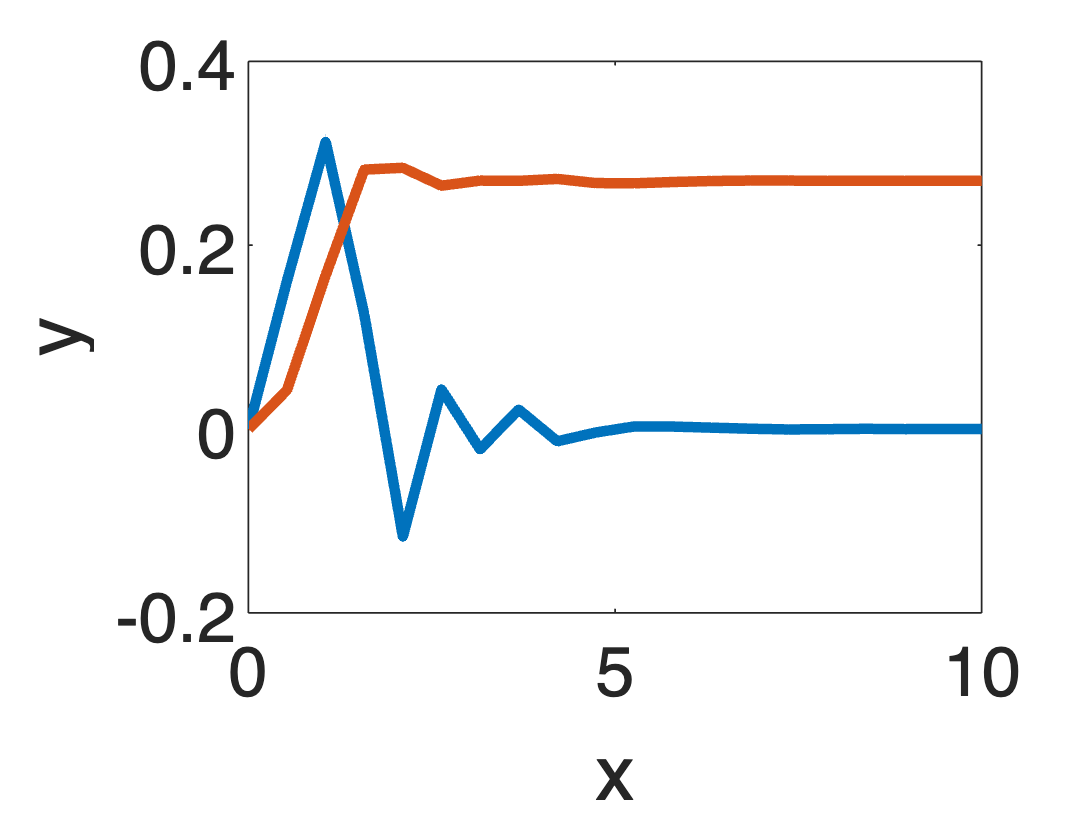

yint = cumtrapz(x,y);
yint_double = cumtrapz(x,yint);

hold off

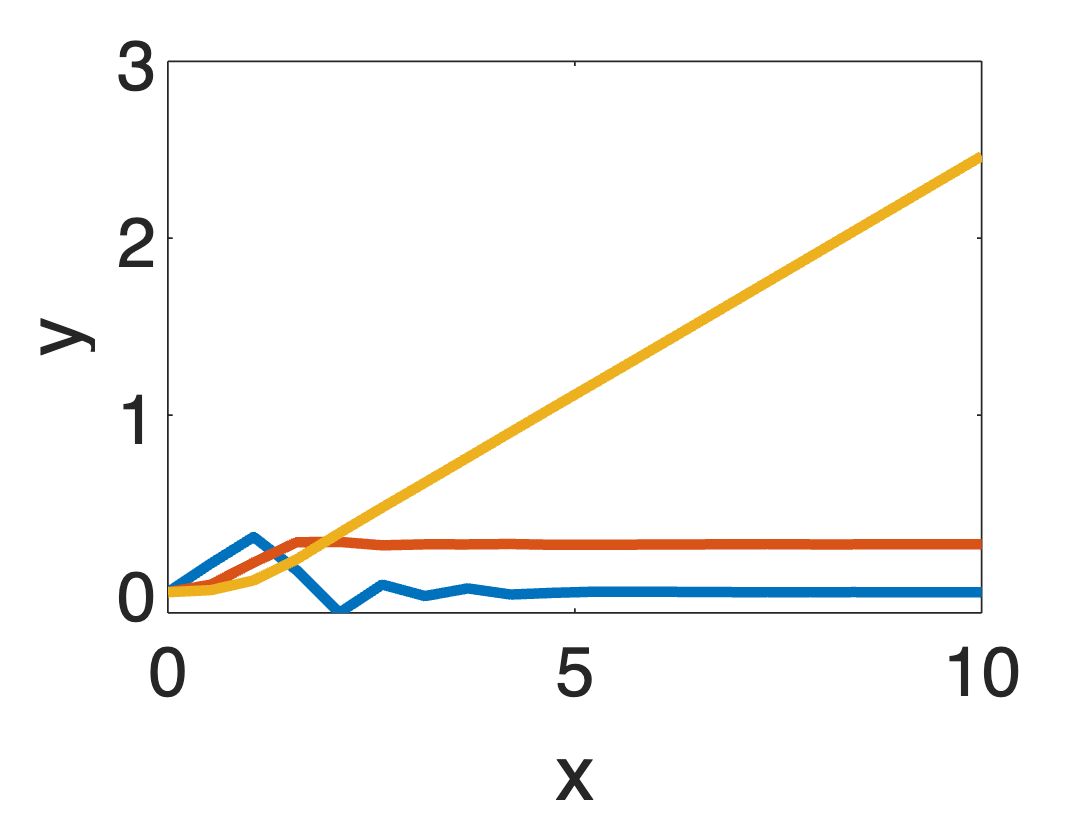

plot(x,y,'linewidth',3);hold on
xlabel('x','FontSize',20)
ylabel('y','FontSize',20)
set(gca,'fontsize',20)

plot(x,yint,'linewidth',3) %note that we need to modify x which has one more element than dydx
%plot(x,yint_double,'linewidth',3)

### Symbolic/Analytical Integrals

To use the symbolic toolbox in MATLAB first you need to define a particular function as being a symbolic data type

syms f(x)
f(x) = exp(-x)*sin(x^2)

$$f(x) = \sin\left(x^{2}\right)\,{\mathrm{e}}^{-x}$$

intf = int(f,x) %this means differential f with respect to x

$$intf(x) = \int \sin\left(x^{2}\right)\,{\mathrm{e}}^{-x}\mathrm{d}x$$

We seem to have defeated the integration abilities of MATLAB. Lets try something else:


$$\int \frac{1}{x^2 +{\left(x-1\right)}^2 }$$


syms g(x)
g(x) = 1/(x^2 + (x-1)^2)

$$g(x) = \frac{1}{{\left(x-1\right)}^{2}+x^{2}}$$

intg = int(g,x)

$$intg(x) = \mathrm{atan}\left(2\,x-1\right)$$

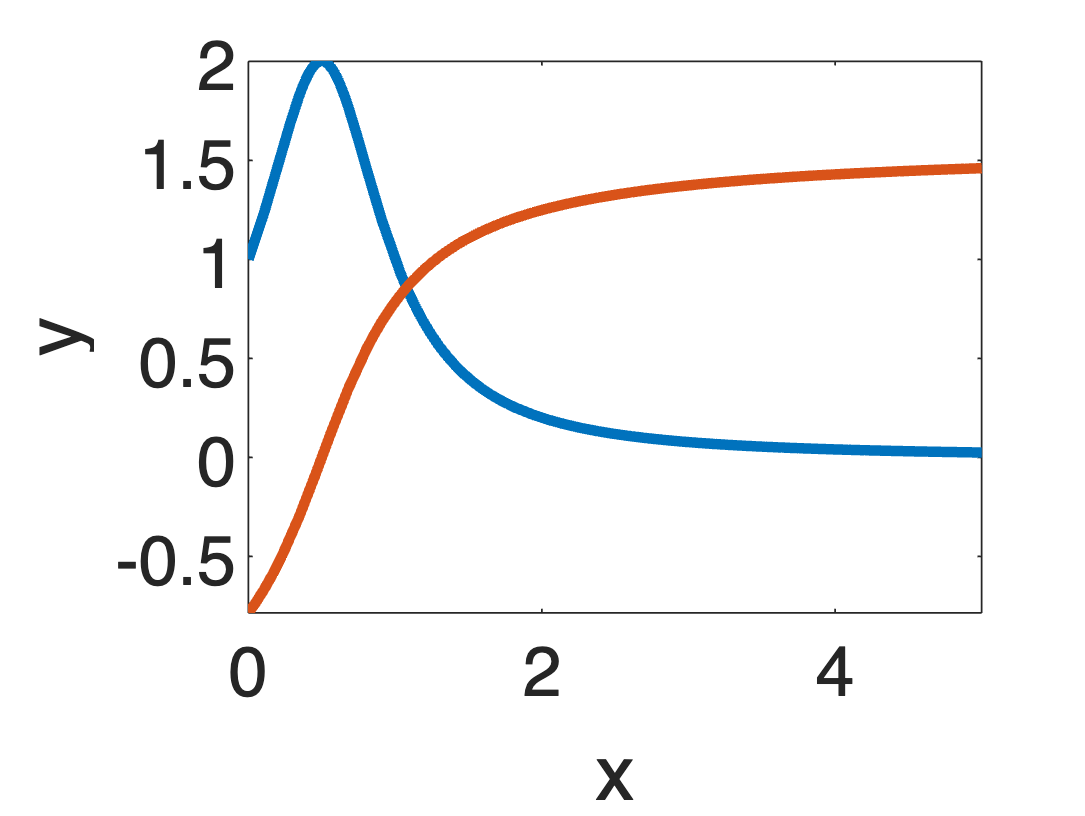

hold off

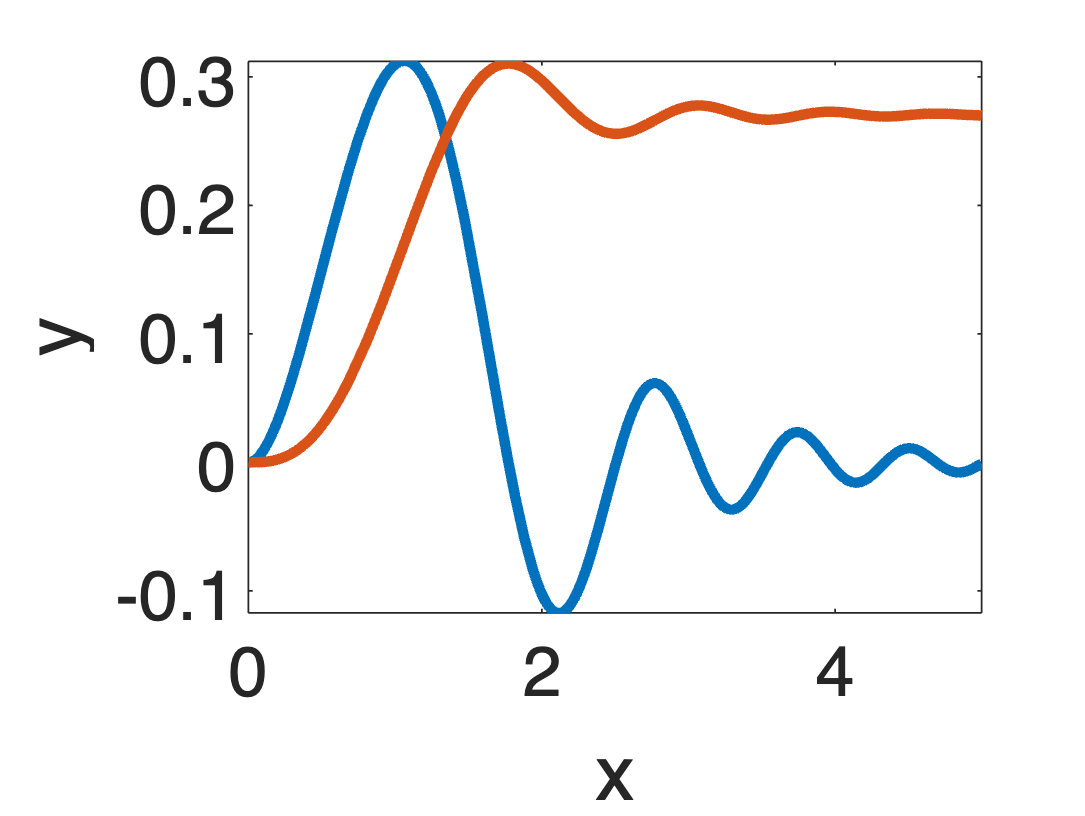

fplot(f,[0 5],'linewidth',3);hold on
xlabel('x','FontSize',20)
ylabel('y','FontSize',20)
set(gca,'fontsize',20)

fplot(intf,[0 5],'linewidth',3);